# CRS-A465: Análisis Cinemático

clear
clc
sympref('AbbreviateOutput', false);

Considere el robot CRS-465 que se encuentra en el Laboratorio de Robótica del Posgrado de la Facultad de Ingeniería, UNAM.

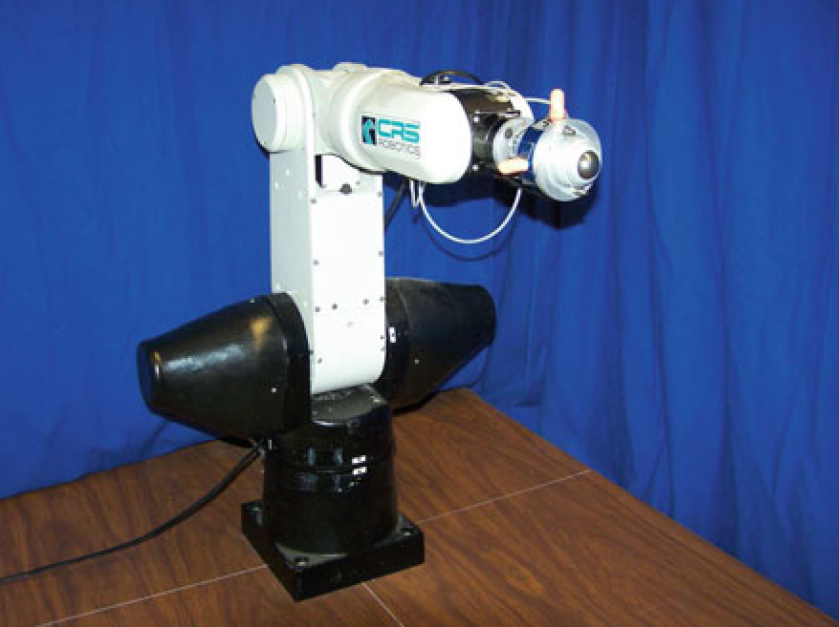

El robot tiene seis grados de libertad, configuración antropomórfica RRR y una muñeca esférica también RRR, con la siguiente arreglo y medidas:

syms q1 q2 q3 q4 q5 q6 
d1 = 0.33;
a2 = 0.34;
d4 = 0.34;
d6 = 0.13;

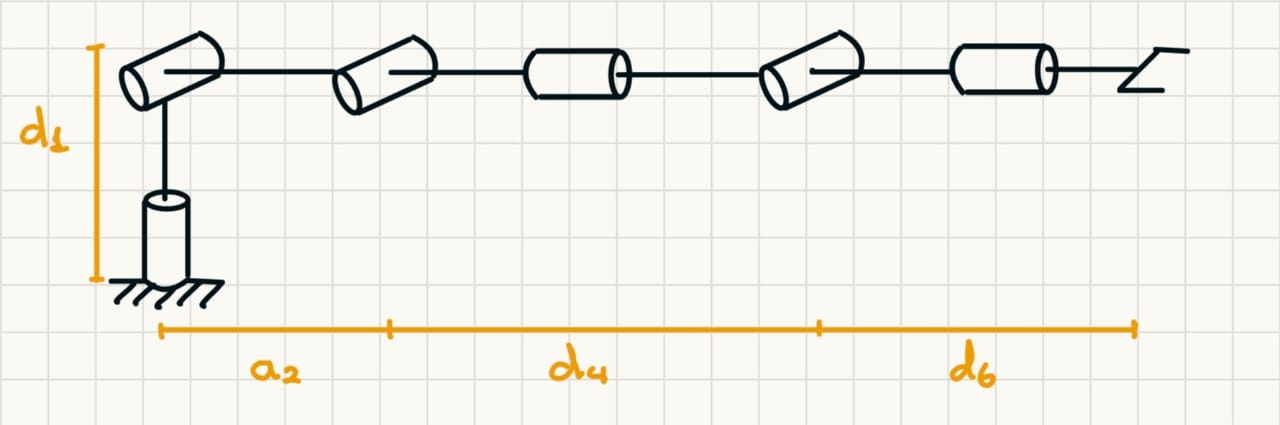

Se desea, a partir de la configuración deseada (un punto $q_d$ en el espacio articular), conocer la posición del efector final (el punto $X$ en el espacio cartesiano) 

qd = [0, 90, -90, 0, 90, 0]';

Y además, a partir de la posición y orientación del efector final $X_d$, conocer la configuración necesaria $q$ para que el robot pueda alcanzar dicho punto.

Xd = [0.2404, 0.2404, 0.33, 20, 45, 25]';

## Cinemática directa

A partir de la configuración deseada del efector final, se encontrará la posición y orientación del efector final.

### Denavit-Hartenberg

Aplicando el algoritmo de Denavit-Hartenberg, se asignan los ejes coordenados de la siguiente forma:

- Se asignan los ejes $z_i$ en la dirección de giro de cada articulación.

- Se establece el origen de cada sistema coordenado $o_i$ con respecto a los ejes $z_{i-1}$ y $z_i$  a) Si $z_{i-1}$ y $z_i$ se cruzan, en su intersección; b) Si $z_{i-1}$ y $z_i$ son paralelos, en cualquier lugar conveniente de $z_i$; c) Si $z_{i-1}$ y $z_i$ no se cruzan ni son paralelos, en la intersección entre $z_i$ y la dirección de la normal de menor tamaño a $z_{i-1}$ y $z_i$.

- Se completa el sistema en la base de forma libre pero respetando que sea un sistema dextrógiro.

- Se colocan los ejes $x_i$ en a) Si $z_{i-1}$ y $z_i$ se cruzan, perpendicular al plano que forman; b) Si $z_{i-1}$ y $z_i$ son paralelos, perpendicular a ambos ejes; c) Si $z_{i-1}$ y $z_i$ no se cruzan ni son paralelos, en la dirección de la normal de menor tamaño a $z_{i-1}$ y $z_i$.

- Se completan todos los sistemas coordenados con $y_i$ de modo que sean sistemas dextrógiros.

- Se asigna el sistema del efector final.

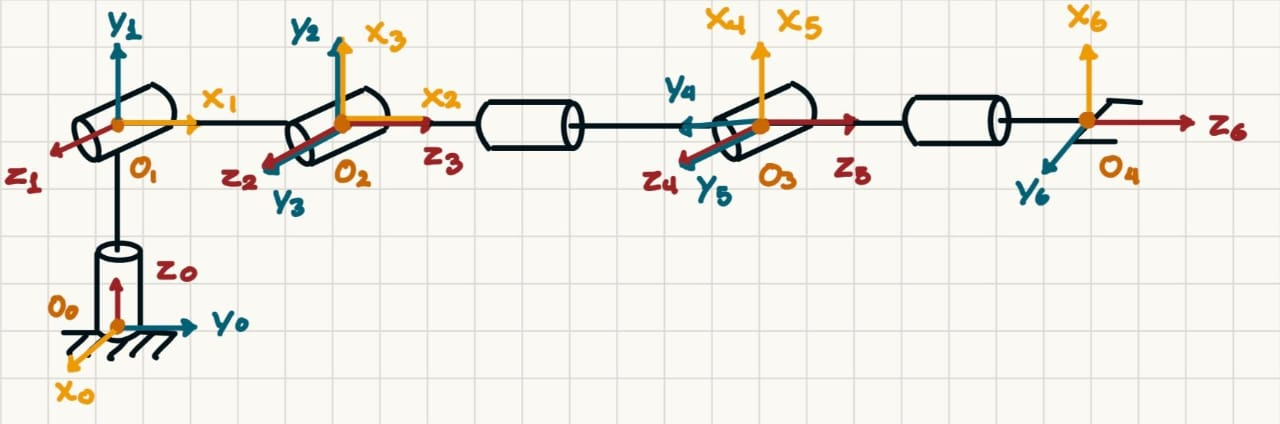

Considerando los ejes coordenados asignados y las dimensiones del robot, se construye la tabla de parámetros DH:

### Transformaciones homogéneas

A partir de la tabla de parámetros DH, se construyen las matrices de transformación entre cada uno de los ejes coordenados .

H1 = Transform.HRz(q1 + 90)  * Transform.HTz(d1) * Transform.HTx(0)  * Transform.HRx(90);
H2 = Transform.HRz(q2)       * Transform.HTz(0)  * Transform.HTx(a2) * Transform.HRx(0);
H3 = Transform.HRz(q3 + 90)  * Transform.HTz(0)  * Transform.HTx(0)  * Transform.HRx(90);
H4 = Transform.HRz(q4)       * Transform.HTz(d4) * Transform.HTx(0)  * Transform.HRx(-90);
H5 = Transform.HRz(q5)       * Transform.HTz(0)  * Transform.HTx(0)  * Transform.HRx(90);
H6 = Transform.HRz(q6)       * Transform.HTz(d6) * Transform.HTx(0)  * Transform.HRx(0);

### Composición de transformaciones

Se construyen las transformaciones homogeneas en cada punto del robot con respecto a la base, extrayendo de ellas las matrices de rotación y los vectores de traslación asociados. Estos últimos pueden utilizarse para verificar las coordenadas de cada sistema asignado al robot.

H01 = H1;
[R01, T01] = Transform.H_DH(H01);
pretty(vpa(subs(T01, {q1}, {qd(1)}),2))

/   0  \
|      |
|   0  |
|      |
\ 0.33 /




H02 = H1*H2;
[R02, T02] = Transform.H_DH(H02);
pretty(vpa(subs(T02, {q1, q2}, {qd(1), qd(2)}),2))

/   0  \
|      |
|   0  |
|      |
\ 0.67 /




H03 = H1*H2*H3;
[R03, T03] = Transform.H_DH(H03);
pretty(vpa(subs(T03, {q1, q2, q3}, {qd(1), qd(2), qd(3)}),2))

/   0  \
|      |
|   0  |
|      |
\ 0.67 /




H04 = H1*H2*H3*H4;
[R04, T04] = Transform.H_DH(H04);
pretty(vpa(subs(T04, {q1, q2, q3, q4}, {qd(1), qd(2), qd(3), qd(4)}),2))

/   0  \
|      |
| 0.34 |
|      |
\ 0.67 /




H05 = H1*H2*H3*H4*H5;
[R05, T05] = Transform.H_DH(H05);
pretty(vpa(subs(T05, {q1, q2, q3, q4, q5}, {qd(1), qd(2), qd(3), qd(4), qd(5)}),2))

/   0  \
|      |
| 0.34 |
|      |
\ 0.67 /




H06 = H1*H2*H3*H4*H5*H6;
[R06, T06] = Transform.H_DH(H06);
pretty(vpa(subs(T06, {q1, q2, q3, q4, q5, q6}, {qd(1), qd(2), qd(3), qd(4), qd(5), qd(6)}),2))

/   0  \
|      |
| 0.34 |
|      |
\  0.8 /



Teniendo la transformación que nos da la ubicación del efector final con respecto a la base $H_6^0$, se sustituye en ella la configuración deseada.

H06_qd = subs(H06, {q1, q2, q3, q4, q5, q6}, {qd(1), qd(2), qd(3), qd(4), qd(5), qd(6)});

Se extraen la matriz de rotación y el vector de traslación.

[R06_qd, T06_qd] = Transform.H_DH(H06_qd);

Las coordenadas cartesianas del efector final serán las mismas que el vector de traslación.

x = T06_qd(1);
y = T06_qd(2);
z = T06_qd(3);

La orientación del efector final se obtiene utilizando Ángulos de Euler con la matriz de rotación.

[phi, theta, psi] = InverseKinematics.eulerAngles(R06_qd);

Finalmente, la ubicación en el espacio cartesiano estará dada por la posición (obtenida del vector de traslación de la transformación homogénea $H_6^0$) y la orientación (obtenida de la matriz de rotación de la transformación homogénea $H_6^0$).

X = [x, y, z, phi, theta, psi]';
pretty(vpa(X, 2))

/   0   \
|       |
|  0.34 |
|       |
|  0.8  |
|       |
|   0   |
|       |
|   0   |
|       |
\ 180.0 /



## Cinemática inversa

El punto en el efector final son las coordenadas $x$, $y$, $z$ deseadas.

o = [Xd(1), Xd(2), Xd(3)]';

Se obtiene la matriz de rotación deseada haciendo rotaciones con los ángulos de Euler (rotaciones respecto al eje actual en el eje $z$ con un ángulo $\phi$, el eje $y$ con un ángulo $\theta$ y en el eje $z$ con un ángulo $\psi$) a partir de los ángulos de la pose deseada.

H = Transform.HRz(X(4))*Transform.HRy(X(5))*Transform.HRz(X(6));
[R, ~] = Transform.H_DH(H);

Se crea el vector $q$ para ser llenado.

q = [0, 0, 0, 0, 0, 0]';

### Punto de desacople

Se obtienen las coordenadas del punto de desacople $o_c$ restándole a la posición deseada $o$ la distancia $d_6$ orientada según la matriz de rotación deseada $R$. 

oc = o - d6 .* R * [0, 0, 1]';

También se obtiene la orientación "faltante" $R_6^3$ para, desde la orientación del punto de desacople $R_3^0$, "alcanzar" a la orientación deseada $R$.

R36 = R03\R;

### Cinemática inversa de 3DOF

En el punto de desacople, se pueden resolver $q_1$, $q_2$ y $q_3$ de la misma manera que si tuvieramos un robot de tres grados de libertad.

[q(1), q(2), q(3)] = InverseKinematics.RRR_antropomorphic(oc, [d1, a2, d4]);

### Ángulos de Euler

Finalmente, para obtener el valor de las tres articulaciones restantes, la matriz de orientación "faltante" $R_6^3$ queda en términos de $q_1$, $q_2$, $q_3$, por lo que sustituyendo estos valores y aplicándole Ángulos de Euler podemos obtener $q_4$, $q_5$ y $q_6$.

R36_qd = subs(R36, {q1, q2, q3}, {qd(1), qd(2), qd(3)});
[phi, theta, psi] = InverseKinematics.eulerAngles(R36_qd);

### Coordenadas cartesianas a coordenadas articulares

q = [q(1), q(2), q(3), phi, theta, psi]';
pretty(vpa(q, 2))

/  45.0 \
|       |
|  37.0 |
|       |
| 120.0 |
|       |
|  90.0 |
|       |
|   0   |
|       |
\ 180.0 /



S